% 12   13    23
% #    #     #  12
%      #     #  13
%            #  23
clear;

gridn=20;
stepx=0.0002;
stepy=0.0001;
stepz=0.0003;
% img=sqrt(1-reshape(linspace(-0.5,0.5,gridn),[gridn,1,1]).^2-reshape(linspace(-0.5,0.5,gridn),[1,gridn,1]).^2-reshape(linspace(-0.5,0.5,gridn),[1,1,gridn]).^2);
img=sqrt(1-reshape((-10:9)*stepy,[gridn,1,1]).^2-reshape((-10:9)*stepx,[1,gridn,1]).^2-reshape((-10:9)*stepz,[1,1,gridn]).^2);
[dx,dy,dz]=gradient(img,stepx,stepy,stepz);
ss=size(img);


df=repmat(reshape([eye(3),zeros([3,1])],[1,1,1,3,4]),[ss,1,1]);
size(df)

ans =     20    20    20     3     4


catd=cat(4,dx,dy,dz);
df(:,:,:,:,4)=catd;
% reshape(df(3,2,1,:,:),[3,4])
g=catd.*reshape(catd,[ss,1,3])+repmat(reshape(eye(3),[1,1,1,3,3]),[ss,1,1]);
size(g)

ans =     20    20    20     3     3


reshape(g(3,2,1,:,:),[3,3])

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000




ig=repmat(reshape(eye(3),[1,1,1,3,3]),[ss,1,1])-catd.*reshape(catd,[ss,1,3])./(repmat(sum(catd.*catd,4),[1,1,1,3,3])+repmat(reshape(ones([3,3]),[1,1,1,3,3]),[ss,1,1]));
% g1=reshape(g(1,2,1,:,:),[3,3])
reshape(ig(1,2,1,:,:),[3,3])

ans =     1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


% g1*g2
n=cat(5,reshape(catd,[ss,1,3]),-ones([ss,1,1]));


n=n./repmat(sqrt(sum(n.^2,5)),[1,1,1,1,4]); 
reshape(n(1,2,2,:,:),[1,4])

ans =     0.0018    0.0010    0.0027   -1.0000


size(n)

ans =     20    20    20     1     4


[dxx,dxy,dxz]=gradient(dx,stepx,stepy,stepz);
[~,dyy,dyz]=gradient(dy,stepx,stepy,stepz);
[~,~,dzz]=gradient(dz,stepx,stepy,stepz);
two=-reshape(cat(4,dxx,dxy,dxz,dxy,dyy,dyz,dxz,dyz,dzz),[ss,3,3])./repmat(sqrt(sum(n.^2,5)),[1,1,1,3,3]);
reshape(two(5,6,9,:,:),[3,3])

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


size(two)

ans =     20    20    20     3     3


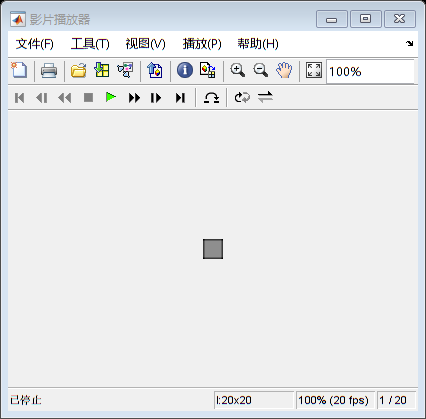

R1212=two(:,:,:,1,1).*two(:,:,:,2,2)-two(:,:,:,1,2).^2;
R1312=two(:,:,:,1,1).*two(:,:,:,2,3)-two(:,:,:,1,2).*two(:,:,:,1,3);
R1313=two(:,:,:,1,1).*two(:,:,:,3,3)-two(:,:,:,1,3).^2;
R2312=two(:,:,:,1,2).*two(:,:,:,2,3)-two(:,:,:,2,2).*two(:,:,:,1,3);
R2313=two(:,:,:,1,2).*two(:,:,:,3,3)-two(:,:,:,2,3).*two(:,:,:,1,3);
R2323=two(:,:,:,2,2).*two(:,:,:,3,3)-two(:,:,:,2,3).^2;
scalar=-2*R1212.*ig(:,:,:,1,2).^2-4*R1312.*ig(:,:,:,1,2).*ig(:,:,:,1,3)+4*R2312.*ig(:,:,:,1,2).*ig(:,:,:,2,3)+4*R2313.*ig(:,:,:,3,3).*ig(:,:,:,1,2)-2*R1313.*ig(:,:,:,1,3).^2-4*R2313.*ig(:,:,:,1,3).*ig(:,:,:,2,3)-4*R2312.*ig(:,:,:,2,2).*ig(:,:,:,1,3)-2*R2323.*ig(:,:,:,2,3).^2+4*R1312.*ig(:,:,:,1,1).*ig(:,:,:,2,3)+2*R1212.*ig(:,:,:,1,1).*ig(:,:,:,2,2)+2*R1313.*ig(:,:,:,1,1).*ig(:,:,:,3,3)+2*R2323.*ig(:,:,:,2,2).*ig(:,:,:,3,3);
implay(mat2gray(scalar))